#### General parameters 

These are the same 'options' used for the filtering and segmentation

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

#### Heart rate extraction from ABP (not used anymore)

Uses difference between location of abp beats

Cannot be used since prediction cannot use features from ABP waveform

% abp_beat_locs = importdata("../physionet.org/segmented_abp_beats/3000393_0016-0022b.txt");
% 
% [hr_avg, hr_max, hr_most_rec] = heartRateFromABP(abp_beat_locs, opts.samp_freq)


#### Heart Rate extraction from PPG

First the beat locations are extracted

Then these are used to find the HR (mean, max, most recent)

data = importdata("../physionet.org/segmented_data/3000393_0005-0001.txt");
beat_locs = beatLocsFromPPG(data(:,3), 220, opts.samp_freq);
[hr_avg, hr_max, hr_most_rec] = heartRateFromBeatLocs(beat_locs, opts.samp_freq)

hr_avg = 77.5437

hr_max = 81.5217

hr_most_rec = 78.9474

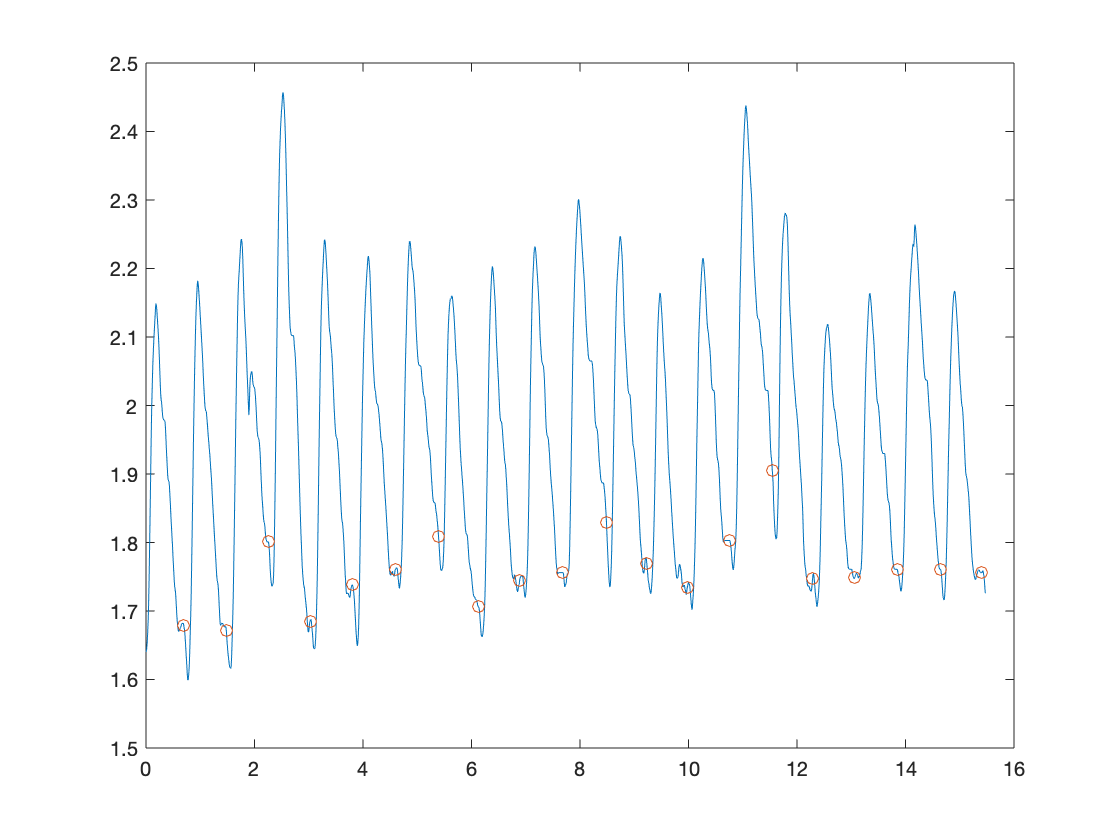

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(beat_locs,1), data(beat_locs,3))

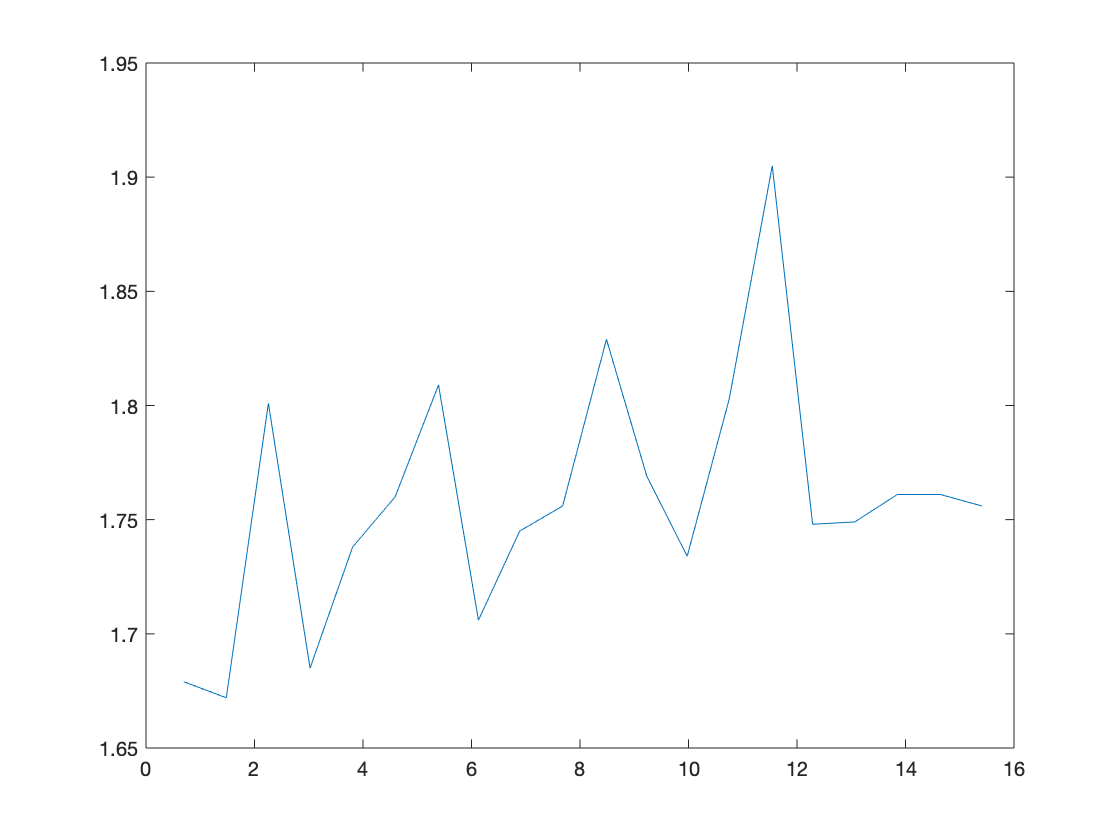

clf
plot(data(beat_locs,1), data(beat_locs,3))

#### Respiratory rate from PPG

See P.S.Addison et al. [https://sci-hub.se/10.1007/s10877-011-9332-y](https://sci-hub.se/10.1007/s10877-011-9332-y)

Typical freq range of respiration is [2.97;28.02] breaths/min <=> [0.05;0.47] Hz. A heart rate of [45;220] bpm <=> [0.75; 3.67] Hz ie. signals should be able to be separated

data = importdata("../physionet.org/segmented_data/3000393_0015-0003.txt");

[filt_num, filt_den] = butter(4,0.55/125,'low');
filt_ppg = filter(filt_num, filt_den, data(:,3));

resp_rate1 = getRespiratoryRateFreq(data(:,1), data(:,3))

resp_rate1 = 0.2528

resp_rate2 = getRespiratoryRateEnv(data(:,3), 125, 0.47)

resp_rate2 = 0.2014

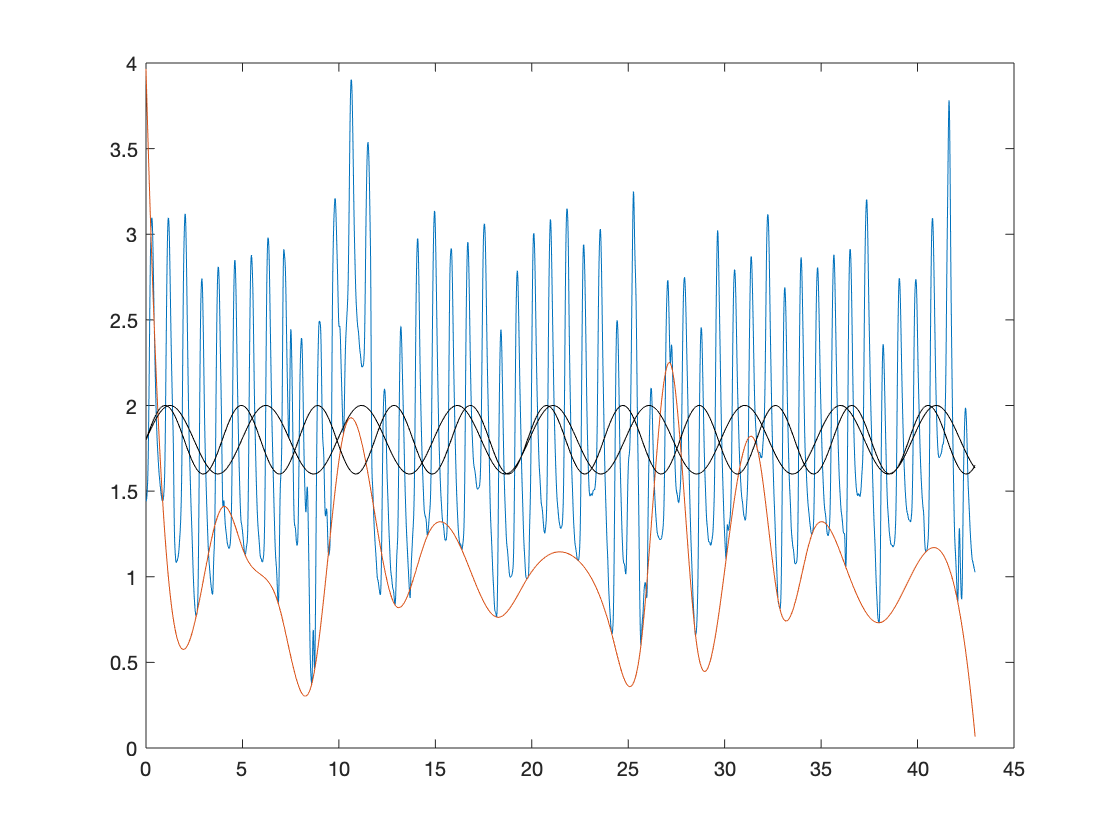


[~,resp_wave] = envelope(data(:,3), 130,'peak');
% getRespiratoryRateFreq(data(:,1), resp_wave)

clf
plot(data(:,1), data(:,3))
hold on
plot(data(:,1), resp_wave)
plot(data(:,1), 0.2.*sin(2*pi*resp_rate1.*data(:,1))+mean(data(:,3)), 'Color', 'black')
plot(data(:,1), 0.2.*sin(2*pi*resp_rate2.*data(:,1))+mean(data(:,3)), 'Color', 'black')



[freq,ppg_fft] = singlesidedFFT( data(:,1),data(:,3));
clf
start_idx = find(freq>=0.05, 1);
end_idx = find(freq>=0.47, 1)-1;
freq_avg = freq(start_idx:end_idx)*abs(ppg_fft(start_idx:end_idx))/sum(abs(ppg_fft(start_idx:end_idx)))

freq_avg = 0.2528

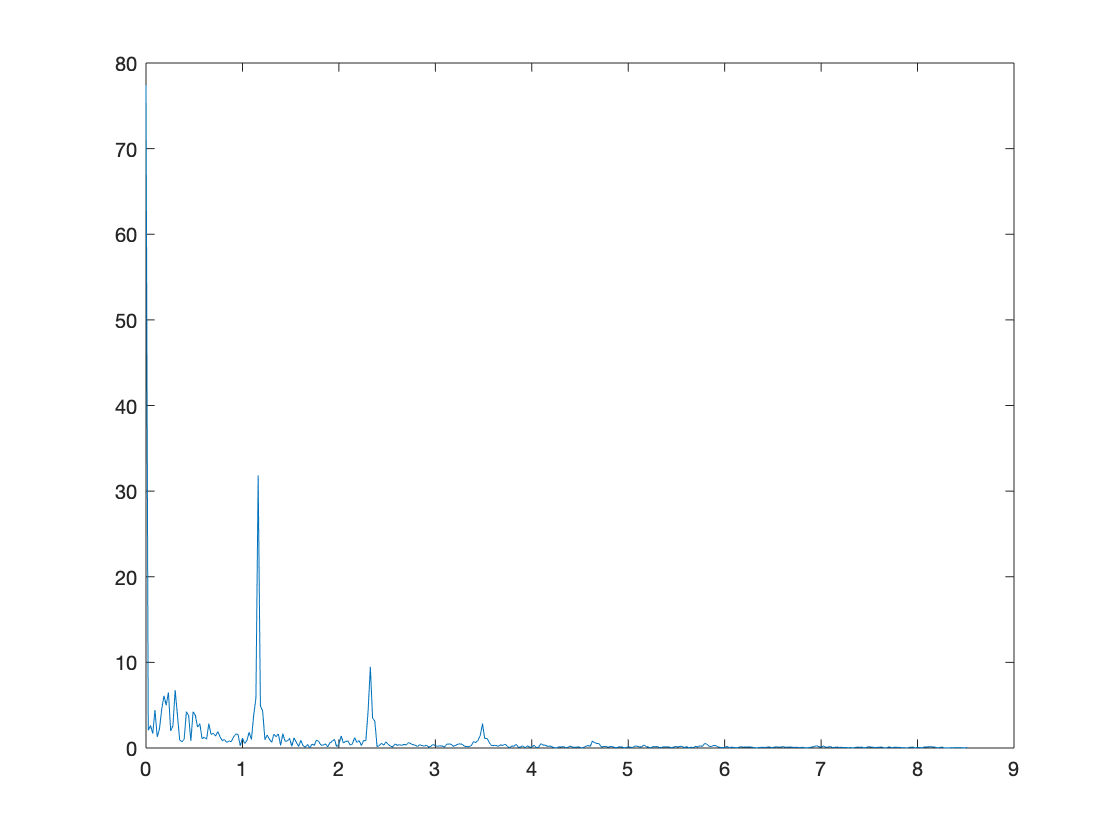

plot(freq(1:b), abs(ppg_fft(1:b)))



function [freqVector, freqSpectrum] = singlesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));
   df = 1/dT;
   %freqVector = (-n/2:(n/2-1))* (df/n);
   freqVector = (0:(n/2 -1)) * (df/n);
   freqSpectrum = fft(timeSignal)/df;
   freqSpectrum(floor(n/2)+1 : end) = [];
   freqSpectrum(2:end) = freqSpectrum(2:end) * 2;
end

function [freqVector, freqSpectrum] = doublesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));
   df = 1/dT;
   freqVector = (-n/2:(n/2-1))* (df/n);
   freqSpectrum = fftshift(fft(timeSignal))/df;
end


